# Fitting a Polynomial

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the data.

data = readtable("data\dataPoly.xlsx", Sheet="data");
dataTrain = readtable("data\dataPoly.xlsx", Sheet="dataTrain");
dataTest = readtable("data\dataPoly.xlsx", Sheet="dataTest");
whos data dataTrain dataTest

  Name             Size            Bytes  Class    Attributes

  data           200x2              4387  table              
  dataTest        60x2              2147  table              
  dataTrain      140x2              3427  table              



## Tasks 1, 2, 3

The table `data` has been split into a training set, `dataTrain`, and a test set, `dataTest`.

Notice the cluster of outliers in the upper left of the plot. You can reduce the influence of the outliers on the model by setting the `"RobustOpts"` property to `"on"`.

mdl = fitlm(dataTrain, "quadratic", "RobustOpts", "on")

mdl = Linear regression model (robust fit):
    y ~ 1 + x + x^2

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     5.0238      0.30936    16.239    9.8525e-34
    x              -3.8354      0.23458    -16.35    5.3118e-34
    x^2             1.0068     0.037078    27.153    5.3891e-57


Number of observations: 140, Error degrees of freedom: 137
Root Mean Squared Error: 1.35
R-squared: 0.946,  Adjusted R-Squared: 0.945
F-statistic vs. constant model: 1.2e+03, p-value = 1.37e-87

yPred = predict(mdl, dataTest);

Plot the results.

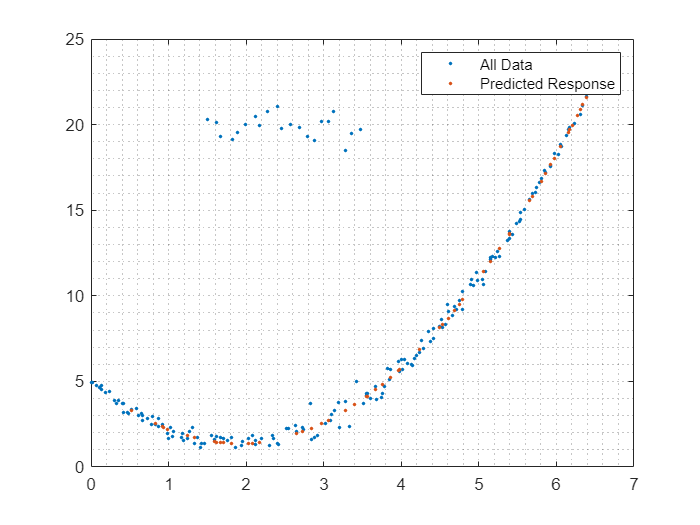

plot(data.x, data.y, ".")
grid minor
hold on
plot(dataTest.x, yPred, ".")
hold off
legend("All Data", "Predicted Response")